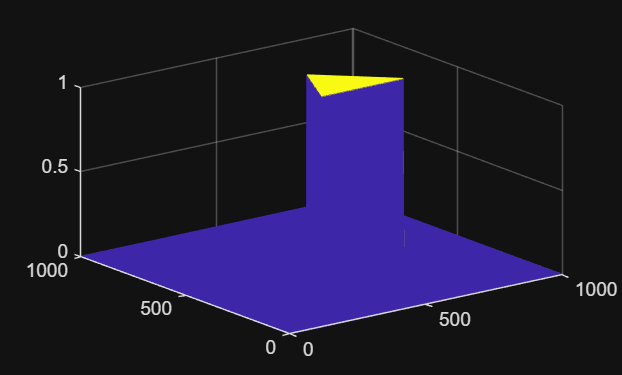

N = 5;
h = 0.01;
[x,y] = meshgrid(-N:h:N);

v1 = [3,0];
v2 = [1,2];
A = [v1' v2'];

dom = zeros(size(x));
[s1,s2] = size(x);

for i = 1:s1
    for j = 1:s2
        a = A^(-1)*[x(i,j) y(i,j)]';
        if a(1) >= 0
            if a(2) >= 0
                if a(1)+a(2)<=1
                    dom(i,j) = 1;
                
                end
            end
        end
    end
end

mesh(dom)